MILESTONE 1

GROUP MEMBERS: Syed Sualeh Abbas, Syed Muhammad Haider Zaidi

clear; close all; clc;

%% PART 1: Loading Data and Basic Information
fprintf('%s\n', repmat('=', 1, 70));

fprintf('MILESTONE 1: CELLO AND TROMBONE SIGNAL ANALYSIS\n');

MILESTONE 1: CELLO AND TROMBONE SIGNAL ANALYSIS


fprintf('%s\n', repmat('=', 1, 70));

% Loading the data files
load('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\Project\cello.mat');
load('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\Project\trombone.mat');

% Displaying basic info
fprintf('\n--- PART 1: BASIC SIGNAL INFORMATION ---\n');


--- PART 1: BASIC SIGNAL INFORMATION ---


fprintf('Cello signal length: %d samples\n', length(cello.x));

Cello signal length: 9288 samples


fprintf('Trombone signal length: %d samples\n', length(trombone.x));

Trombone signal length: 9288 samples


## Q1.  How long are the recorded samples in time (seconds)?

% Calculating lenth of signal (time)
cello_time = cello.dt * length(cello.x);
trombone_time = trombone.dt * length(trombone.x);

fprintf('Cello recording duration: %.4f seconds\n', cello_time);

Cello recording duration: 1.1338 seconds


fprintf('Trombone recording duration: %.4f seconds\n', trombone_time);

Trombone recording duration: 1.1338 seconds


## Q2. What are the frequencies of the cello and trombone keynotes?

% Sampling frequencies
cello_fs = 1/cello.dt;
trombone_fs = 1/trombone.dt;

fprintf('Cello sampling frequency: %.2f Hz\n', cello_fs);

Cello sampling frequency: 8192.00 Hz


fprintf('Trombone sampling frequency: %.2f Hz\n', trombone_fs);

Trombone sampling frequency: 8192.00 Hz



% Creating time vectors
t_cello = (0:length(cello.x)-1) * cello.dt;
t_trombone = (0:length(trombone.x)-1) * trombone.dt;

% Computing spectra for both of the signals
N_cello = length(cello.x);
N_trombone = length(trombone.x);

% Use pwelch for spectrum estimation
[cello_pxx, f_cello] = pwelch(cello.x, hamming(min(512, N_cello/4)), [], [], cello_fs);
[trombone_pxx, f_trombone] = pwelch(trombone.x, hamming(min(512, N_trombone/4)), [], [], trombone_fs);

% Converting to dB
P_cello = 10*log10(cello_pxx + eps);
P_trombone = 10*log10(trombone_pxx + eps);

% Finding keynote frequencies (which is fundamental)-marking for strongest peak in 50-500 Hz
low_range_cello = f_cello >= 50 & f_cello <= 500;
[~, idx_cello] = max(P_cello(low_range_cello));
cello_keynote = f_cello(find(low_range_cello, 1) + idx_cello - 1);

low_range_trombone = f_trombone >= 50 & f_trombone <= 500;
[~, idx_trombone] = max(P_trombone(low_range_trombone));
trombone_keynote = f_trombone(find(low_range_trombone, 1) + idx_trombone - 1);

fprintf('Cello keynote frequency: %.2f Hz\n', cello_keynote);

Cello keynote frequency: 224.00 Hz


fprintf('Trombone keynote frequency: %.2f Hz\n', trombone_keynote);

Trombone keynote frequency: 224.00 Hz


%% PART 3: Overtone Analysis - Integer Multiples Check

% Finding the peak frequencies
[pks_cello, locs_cello] = findpeaks(P_cello, 'MinPeakHeight', max(P_cello)-40, ...
                                      'MinPeakDistance', 10);
peak_freqs_cello = f_cello(locs_cello);

[pks_trombone, locs_trombone] = findpeaks(P_trombone, 'MinPeakHeight', max(P_trombone)-40, ...
                                            'MinPeakDistance', 10);
peak_freqs_trombone = f_trombone(locs_trombone);

% Checking the test for harmonic relationship
fprintf('\nCello overtones (keynote = %.2f Hz):\n', cello_keynote);


Cello overtones (keynote = 224.00 Hz):


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------


fprintf('Peak Freq (Hz)\t\tRatio to Keynote\tExpected Harmonic\n');

Peak Freq (Hz)		Ratio to Keynote	Expected Harmonic


for i = 1:min(10, length(peak_freqs_cello))
    ratio = peak_freqs_cello(i) / cello_keynote;
    harmonic = round(ratio);
    error_pct = abs(ratio - harmonic) / harmonic * 100;
    if error_pct < 5 && harmonic > 1
        fprintf('%.2f\t\t\t%.3f (k=%d)\t\tMatch (error=%.2f%%)\n', ...
                peak_freqs_cello(i), ratio, harmonic, error_pct);
    elseif harmonic == 1
        fprintf('%.2f\t\t\t%.3f (k=%d)\t\tKEYNOTE\n', ...
                peak_freqs_cello(i), ratio, harmonic);
    else
        fprintf('%.2f\t\t\t%.3f\t\t\tNoise/Non-harmonic\n', ...
                peak_freqs_cello(i), ratio);
    end
end

48.00			0.214			Noise/Non-harmonic


224.00			1.000 (k=1)		KEYNOTE


448.00			2.000 (k=2)		Match (error=0.00%)
656.00			2.929 (k=3)		Match (error=2.38%)
880.00			3.929 (k=4)		Match (error=1.79%)
1104.00			4.929 (k=5)		Match (error=1.43%)
1328.00			5.929 (k=6)		Match (error=1.19%)
1552.00			6.929 (k=7)		Match (error=1.02%)
1776.00			7.929 (k=8)		Match (error=0.89%)
1984.00			8.857 (k=9)		Match (error=1.59%)


## Q3. Do the overtones appear at integer multiples of the keynotes?

Ans: Yes, overtone appears at integer multiples of the keynote frequency. That means the Harmonic frequency is followin gthe relation of Fk = Fo x k with some minor errors. But we know that overtones can have a small error of about 5% or less. The max error that we calculated is 2.38% which is still very close to original signal.

fprintf('\nTrombone overtones (keynote = %.2f Hz):\n', trombone_keynote);


Trombone overtones (keynote = 224.00 Hz):


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------


fprintf('Peak Freq (Hz)\t\tRatio to Keynote\tExpected Harmonic\n');

Peak Freq (Hz)		Ratio to Keynote	Expected Harmonic


for i = 1:min(10, length(peak_freqs_trombone))
    ratio = peak_freqs_trombone(i) / trombone_keynote;
    harmonic = round(ratio);
    error_pct = abs(ratio - harmonic) / harmonic * 100;
    if error_pct < 5 && harmonic > 1
        fprintf('%.2f\t\t\t%.3f (k=%d)\t\tMatch (error=%.2f%%)\n', ...
                peak_freqs_trombone(i), ratio, harmonic, error_pct);
    elseif harmonic == 1
        fprintf('%.2f\t\t\t%.3f (k=%d)\t\tKEYNOTE\n', ...
                peak_freqs_trombone(i), ratio, harmonic);
    else
        fprintf('%.2f\t\t\t%.3f\t\t\tNoise/Non-harmonic\n', ...
                peak_freqs_trombone(i), ratio);
    end
end

48.00			0.214			Noise/Non-harmonic


224.00			1.000 (k=1)		KEYNOTE


448.00			2.000 (k=2)		Match (error=0.00%)
672.00			3.000 (k=3)		Match (error=0.00%)
880.00			3.929 (k=4)		Match (error=1.79%)
1104.00			4.929 (k=5)		Match (error=1.43%)


## 4. How many overtones can you see for the cello and the trombone sounds? (Hint: use  the logarithmic scale for magnitude).

%% PART 4: Count Detectable Overtones (FIXED)

% Converting magnitude spectrum to dB (log scaling will be required for visibility)
mag_cello_db = P_cello;
mag_trombone_db = P_trombone;

% Threshold: 30 dB below fundamental peak, below it, all will be ignored.
threshold_cello = max(mag_cello_db) - 30;
threshold_trombone = max(mag_trombone_db) - 30;

% Ensure half-spectrum consistency
N_cello_half = length(f_cello);
N_trombone_half = length(f_trombone);

% Finding peaks in spectrum
[peaks_c, locs_c] = findpeaks(mag_cello_db, f_cello, ...
    'MinPeakHeight', threshold_cello, ...
    'MinPeakDistance', 20);

[peaks_t, locs_t] = findpeaks(mag_trombone_db, f_trombone, ...
    'MinPeakHeight', threshold_trombone, ...
    'MinPeakDistance', 20);

% Fundamental frequency, we dont need to count it in overtones
fundamental_c = cello_keynote;
fundamental_t = trombone_keynote;

% Keep only overtones
overtone_locs_c = locs_c(locs_c > fundamental_c * 1.1);
overtone_locs_t = locs_t(locs_t > fundamental_t * 1.1);

% FINAL Counts
overtone_count_cello = length(overtone_locs_c);
overtone_count_trombone = length(overtone_locs_t);
fprintf('Cello: %d detectable overtones\n', overtone_count_cello);

Cello: 10 detectable overtones


if overtone_count_cello > 0
    fprintf('Cello overtone frequencies: ');
    fprintf('%.1f Hz ', overtone_locs_c);
    fprintf('\n');
end

Cello overtone frequencies: 

448.0 Hz 656.0 Hz 880.0 Hz 1104.0 Hz 1328.0 Hz 1552.0 Hz 1776.0 Hz 1984.0 Hz 2208.0 Hz 2432.0 Hz 

fprintf('Trombone: %d detectable overtones\n', overtone_count_trombone);

Trombone: 4 detectable overtones


if overtone_count_trombone > 0
    fprintf('Trombone overtone frequencies: ');
    fprintf('%.1f Hz ', overtone_locs_t);
    fprintf('\n');
end

Trombone overtone frequencies: 

448.0 Hz 672.0 Hz 880.0 Hz 1104.0 Hz 

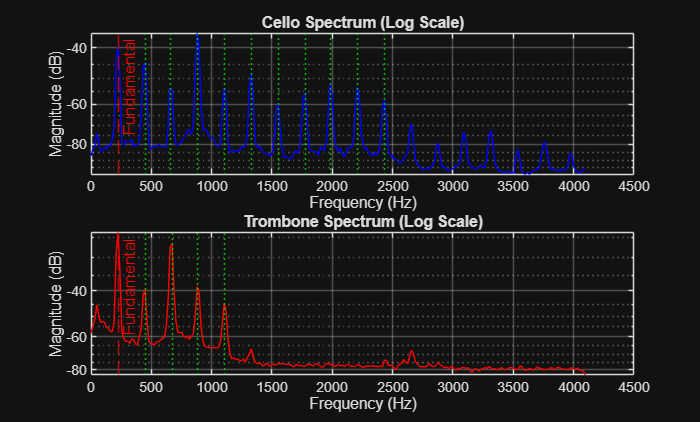

%% VISUAL CHECK
figure;

subplot(2,1,1);
semilogy(f_cello, mag_cello_db, 'b');
hold on;
xline(fundamental_c, 'r--', 'Fundamental');
xline(overtone_locs_c, 'g:');
title('Cello Spectrum (Log Scale)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

subplot(2,1,2);
semilogy(f_trombone, mag_trombone_db, 'r');
hold on;
xline(fundamental_t, 'r--', 'Fundamental');
xline(overtone_locs_t, 'g:');
title('Trombone Spectrum (Log Scale)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

First we converted signal into its frequency domain, then we plotted the magnitude of it with the logrithmic scale. We need a certain threshold above which we observe the overtones and other peaks below it are ignored. Th efundamental frequency was excluded from the counting of overtones and remaining stronger peaks are counted as overtones.

%% PART 5: Noise Analysis - Safe Version (No logical scalar error)

band_width = 2;

% Cello
mask50_cello = (f_cello >= 50-band_width) & (f_cello <= 50+band_width);
mask60_cello = (f_cello >= 60-band_width) & (f_cello <= 60+band_width);

power_50_cello = max(P_cello(mask50_cello));
power_60_cello = max(P_cello(mask60_cello));

% Ensuring the safety of scalar
power_50_cello = max(power_50_cello);
power_60_cello = max(power_60_cello);

% Trombone 
mask50_trombone = (f_trombone >= 50-band_width) & (f_trombone <= 50+band_width);
mask60_trombone = (f_trombone >= 60-band_width) & (f_trombone <= 60+band_width);

power_50_trombone = max(P_trombone(mask50_trombone));
power_60_trombone = max(P_trombone(mask60_trombone));

%ensuring the scalar safety
power_50_trombone = max(power_50_trombone);
power_60_trombone = max(power_60_trombone);
fprintf('Cello - 50 Hz: %.2f dB | 60 Hz: %.2f dB\n', power_50_cello, power_60_cello);

Cello - 50 Hz: -74.06 dB | 60 Hz:  dB


fprintf('Trombone - 50 Hz: %.2f dB | 60 Hz: %.2f dB\n', power_50_trombone, power_60_trombone);

Trombone - 50 Hz: -45.25 dB | 60 Hz:  dB


% FINAL SAFE DECISION
if all([power_50_cello > power_60_cello, power_50_trombone > power_60_trombone])
    fprintf('\n>>> POSSIBLE 50 Hz MAINS HUM DETECTED <<<\n');

elseif all([power_60_cello > power_50_cello, power_60_trombone > power_50_trombone])
    fprintf('\n>>> POSSIBLE 60 Hz MAINS HUM DETECTED <<<\n');

else
    fprintf('\n>>> NO STRONG DOMINANT POWER LINE HUM DETECTED <<<\n');
end


>>> POSSIBLE 50 Hz MAINS HUM DETECTED <<<


## Q5. These sounds were recorded using a really bad tape-recorder, and thus contain a lot of noise. Can you see a strong noise peak at a particular frequency? What is the  significance of that particular frequency? (Hint: the tape recorder was not battery  charged.)

ANS: As we can see some possible peaks were detected at 50Hz, which explains: the radio was not battery powered hence it was powered by the power lines. usually the power lines operate at the frequency of 50-60Hz which might cause some noise at those frequency in the recording due to interfrence. No such peak on 60Hz was detected, but the peak was detected upon 50Hz that means strnger noise was detected over 50Hz. If the recorded was battery powered, it would operate on DC constant source which would have avoided this situaltion. Rightnow the at 50Hz a chracterstic electrical humming is introduced in the orignal signal.

## Q6.a

%% PART 6: Cello Corruption Analysis
fprintf('Corruption formula: CelloCorrupted[n] = n * cello[2n + 1] + 5\n');

Corruption formula: CelloCorrupted[n] = n * cello[2n + 1] + 5


fprintf('(where n = 0, 1, 2, ...)\n');

(where n = 0, 1, 2, ...)


% Simulating corrupted data
N_cello_orig = length(cello.x);
max_n = floor((N_cello_orig - 1) / 2);
n_range = 0:max_n; 

cello_corrupted = zeros(1, length(n_range));

for idx = 1:length(n_range)
    n = n_range(idx);
    orig_idx = 2*n + 1;  % indexing at 1 base
    
    if orig_idx <= N_cello_orig
        cello_corrupted(idx) = n * cello.x(orig_idx) + 5;
    end
end

fprintf('Original cello length: %d samples\n', N_cello_orig);

Original cello length: 9288 samples


fprintf('Corrupted cello length: %d samples\n', length(cello_corrupted));

Corrupted cello length: 4644 samples


## Q6.b: Assuming that you have access only to the corrupted data and the  corruption formula above, do you think it is possible to recover the original  data? (Justify your answer).

ANS: The corrupted cello signal was generated using the provided transformation, where each sample output depends on the shifted index of the orignal signal (2n+1). Full recovery of the signal is definetly not possible as the corrupted signal just discards half of the orriginal signal, so most of the data just gets lost which is not reconstructable. Only the samples that were actually used in the corruption process can be recovered by reversing the equation, while the rest of the original signal remains permanently lost. thats why only partial reconstruction can happen.

## Q6.c

% Question 6c: Recovery code

cello_recovered = NaN(1, N_cello_orig);  

for idx = 1:length(n_range)
    n = n_range(idx);
    
    if n > 0 
        orig_idx = 2*n + 1;
        
        if orig_idx <= N_cello_orig
            cello_recovered(orig_idx) = (cello_corrupted(idx) - 5) / n;
        end
    end
end
recovered_count = sum(~isnan(cello_recovered)); 

fprintf('Recovery completed.\n');

Recovery completed.


fprintf('Recovered samples: %d out of %d (%.1f%%)\n', ...
        recovered_count, N_cello_orig, ...
        100 * recovered_count / N_cello_orig);

Recovered samples: 4643 out of 9288 (50.0%)



fprintf('Note: Even-indexed samples and index 1 remain unknown.\n');

Note: Even-indexed samples and index 1 remain unknown.


## Q7a. Similarly assume that the trombone recording got corrupted in the following way tromboneCorrupted[n] = 1/2  (trombone[n] + trombone[n-1]). Simulate the corrupted data. What has the buggy component done to the  signal?

ANS: The buggy component is a 2-point moving average filter that replaces each sample with the average of itself and the previous sample, resulting in a smoothed (low-pass filtered) version of the signal.

%% PART 7: Trombone Corruption Analysis
fprintf('Corruption formula: TromboneCorrupted[n] = 0.5 * (trombone[n] + trombone[n-1])\n');

Corruption formula: TromboneCorrupted[n] = 0.5 * (trombone[n] + trombone[n-1])


fprintf('(for n >= 1, with appropriate boundary conditions)\n');

(for n >= 1, with appropriate boundary conditions)



% Simulating corrupted data
N_trombone_orig = length(trombone.x);
trombone_corrupted = zeros(1, N_trombone_orig);

% defining first sample
trombone_corrupted(1) = trombone.x(1);

% n starts from 2 (1-based) to avoid trombone[0]
for n = 2:N_trombone_orig
    trombone_corrupted(n) = 0.5 * (trombone.x(n) + trombone.x(n-1));
end

fprintf('Original trombone length: %d samples\n', N_trombone_orig);

Original trombone length: 9288 samples


fprintf('Corrupted trombone length: %d samples\n', length(trombone_corrupted));

Corrupted trombone length: 9288 samples


## Q7b. Assuming that you have access only to the corrupted data and the  corrupting formula above, do you think it is possible to recover the original  data? (Justify your answer).

ANS: In theory all original signal points can be recovered as the corrupted signal is not deleting the values. By rearraging the givem equation, we can just reconstruct the original samples step by step by corrupted signal and previous recovered value. But even a small error can keep building up as we move forward leading to some errors or corruption in the recovered data. it may not be the best recovery.

## Q7.c

% Question 7c: Recovery code

% Recovering using sequential inverse operation of corrupted ddata
trombone_recovered = zeros(1, N_trombone_orig);
trombone_recovered(1) = trombone_corrupted(1);

for n = 2:N_trombone_orig
    trombone_recovered(n) = 2 * trombone_corrupted(n) - trombone_recovered(n-1);
end

fprintf('Recovery completed using sequential method.\n');

Recovery completed using sequential method.


fprintf('Recovery formula: x[n] = 2*y[n] - x[n-1]\n');

Recovery formula: x[n] = 2*y[n] - x[n-1]


fprintf('Note: Recovery assumes knowledge of x[1] as boundary condition.\n');

Note: Recovery assumes knowledge of x[1] as boundary condition.


%% VISUALIZATION SECTION
fprintf('\n--- GENERATING PLOTS ---\n');


--- GENERATING PLOTS ---


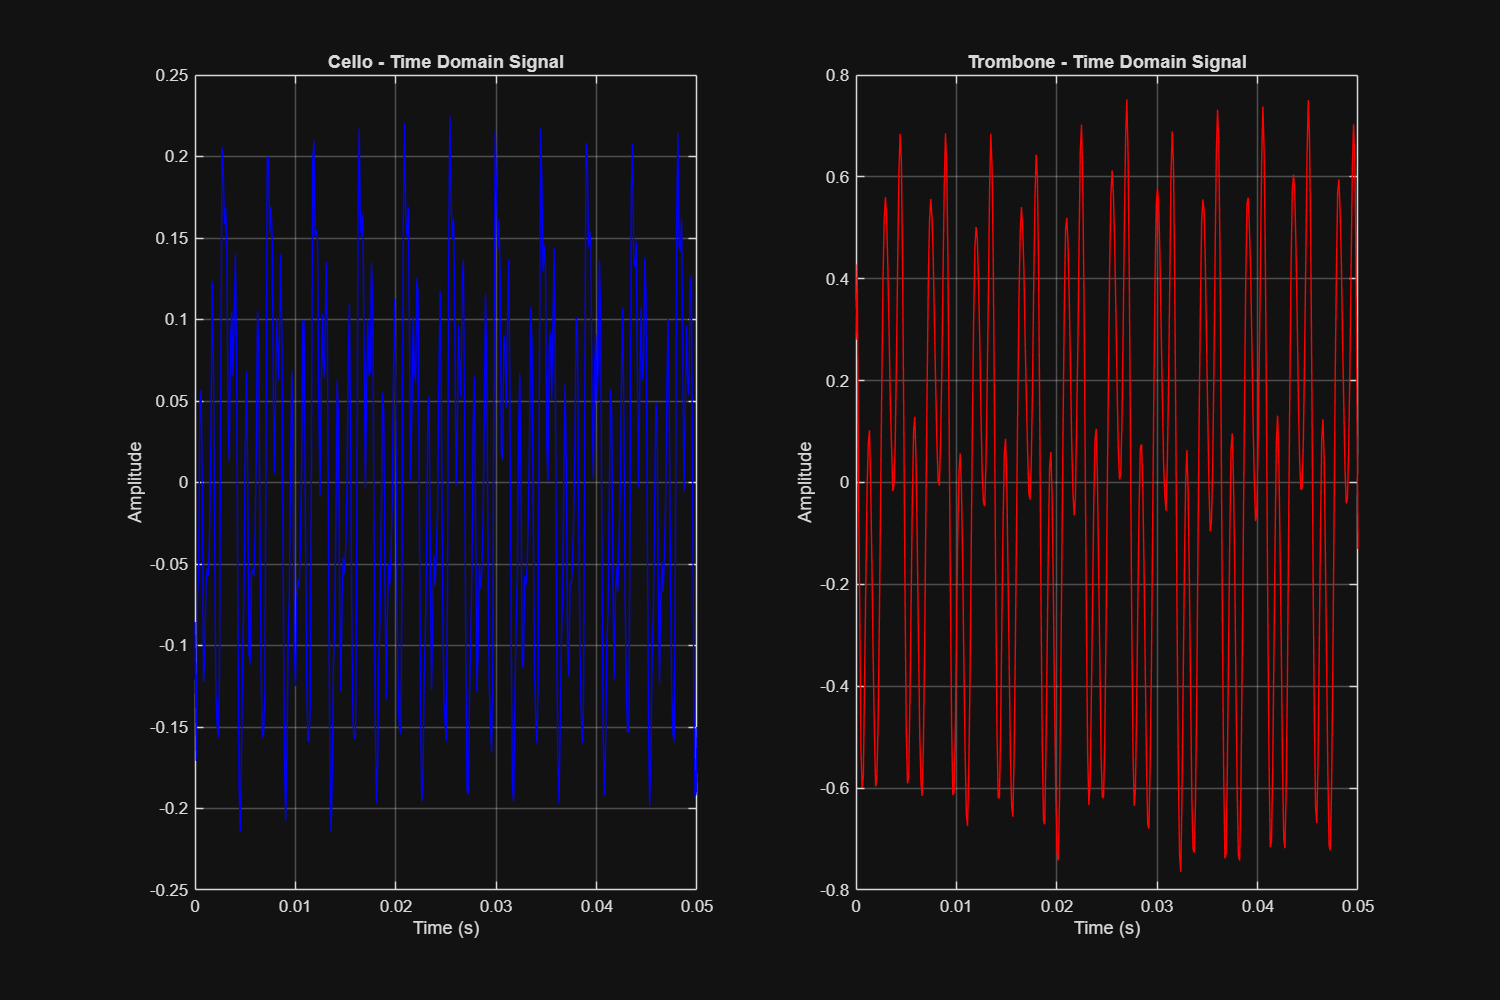


%% Figure 1: Time domain signals

figure('Position', [100, 100, 1200, 800]);

subplot(1,2,1);
plot(t_cello, cello.x, 'b-');
xlabel('Time (s)');
ylabel('Amplitude');
title('Cello - Time Domain Signal');
grid on;
xlim([0, min(0.05, t_cello(end))]);

subplot(1,2,2);
plot(t_trombone, trombone.x, 'r-');
xlabel('Time (s)');
ylabel('Amplitude');
title('Trombone - Time Domain Signal');
grid on;
xlim([0, min(0.05, t_trombone(end))]);
xlim([0, min(0.05, cello_time)]);

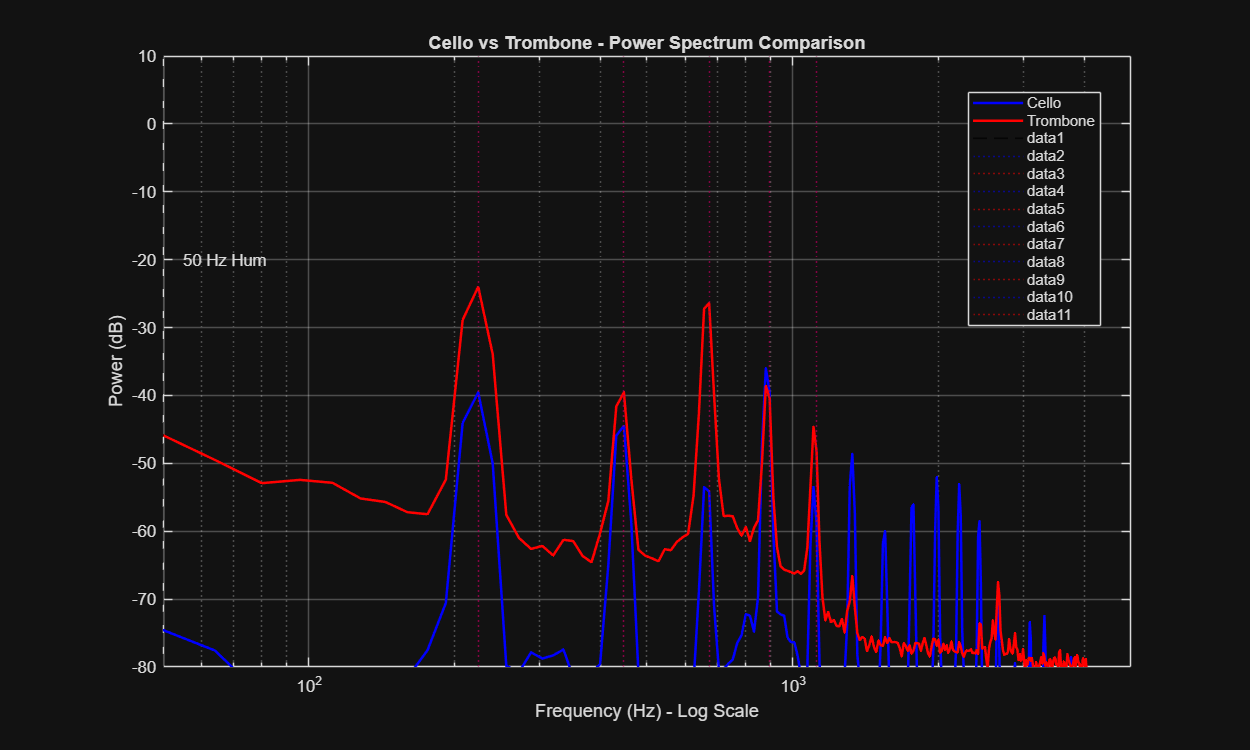

% Figure 3: Overtone comparison (log frequency scale)
figure('Position', [100, 100, 1000, 600]);

semilogx(f_cello, P_cello, 'b-', 'LineWidth', 1.5); 
hold on;
semilogx(f_trombone, P_trombone, 'r-', 'LineWidth', 1.5);
xlabel('Frequency (Hz) - Log Scale'); 
ylabel('Power (dB)');
title('Cello vs Trombone - Power Spectrum Comparison');
grid on; 
xlim([50, 5000]);
ylim([-80, 10]);
legend('Cello', 'Trombone', 'Location', 'best');

% Mark 50 Hz noise
xline(50, 'k--', 'LineWidth', 1);
text(55, -20, '50 Hz Hum', 'FontSize', 10);

% Mark harmonics for both instruments
for k = 1:5
    harmonic_cello = k * cello_keynote;
    harmonic_trombone = k * trombone_keynote;
    if harmonic_cello < 5000
        xline(harmonic_cello, 'b:', 'Alpha', 0.5);
    end
    if harmonic_trombone < 5000
        xline(harmonic_trombone, 'r:', 'Alpha', 0.5);
    end
end
hold off;

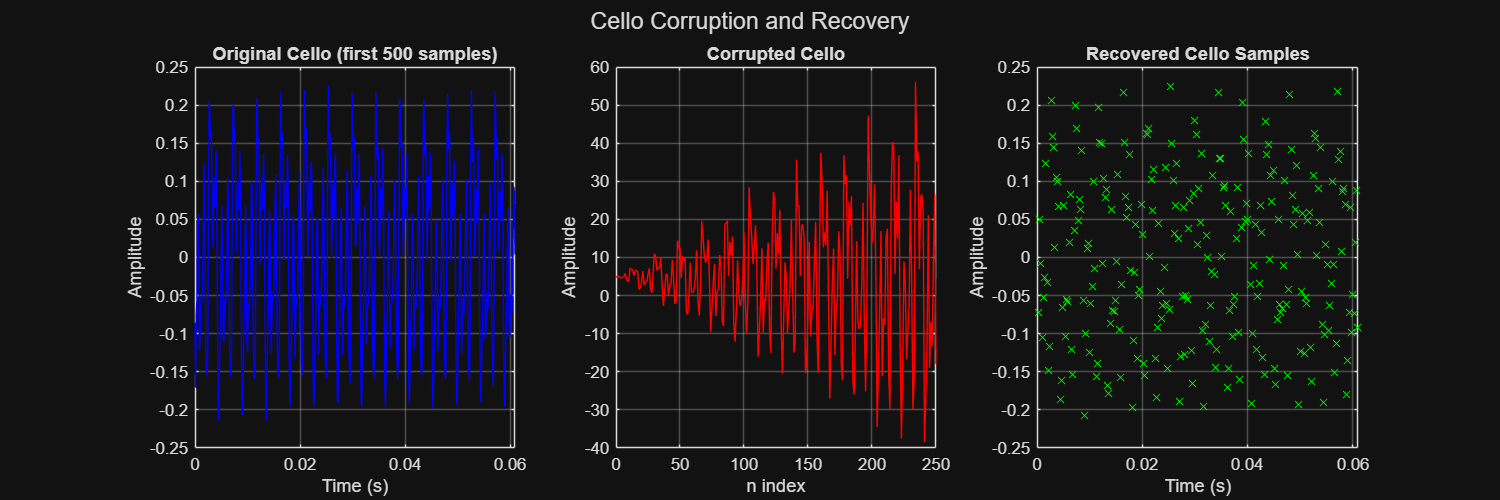


% Figure 4: Corruption effects on cello
figure('Position', [100, 100, 1200, 400]);

subplot(1,3,1);
plot(t_cello(1:min(500, N_cello_orig)), cello.x(1:min(500, N_cello_orig)), 'b-');
xlabel('Time (s)'); ylabel('Amplitude');
title('Original Cello (first 500 samples)');
grid on;

subplot(1,3,2);
n_plot = 0:min(250, length(cello_corrupted)-1);
plot(n_plot, cello_corrupted(1:length(n_plot)), 'r-');
xlabel('n index'); ylabel('Amplitude');
title('Corrupted Cello');
grid on;

subplot(1,3,3);
orig_idx_recovered = 2*n_plot + 1;
valid_recovered = orig_idx_recovered <= N_cello_orig;
plot(t_cello(orig_idx_recovered(valid_recovered)), ...
     cello_recovered(orig_idx_recovered(valid_recovered)), 'gx');
xlabel('Time (s)'); ylabel('Amplitude');
title('Recovered Cello Samples');
grid on;

sgtitle('Cello Corruption and Recovery');

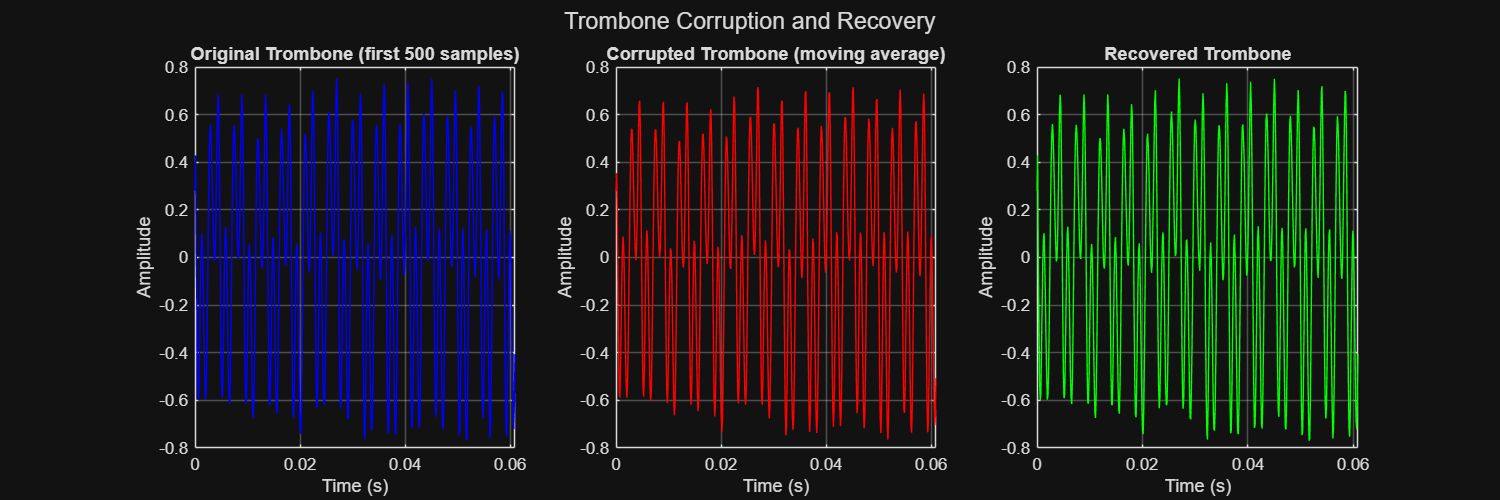


% Figure 5: Trombone filter effect
figure('Position', [100, 100, 1200, 400]);

subplot(1,3,1);
plot(t_trombone(1:min(500, N_trombone_orig)), trombone.x(1:min(500, N_trombone_orig)), 'b-');
xlabel('Time (s)'); ylabel('Amplitude');
title('Original Trombone (first 500 samples)');
grid on;

subplot(1,3,2);
plot(t_trombone(1:min(500, N_trombone_orig)), trombone_corrupted(1:min(500, N_trombone_orig)), 'r-');
xlabel('Time (s)'); ylabel('Amplitude');
title('Corrupted Trombone (moving average)');
grid on;

subplot(1,3,3);
plot(t_trombone(1:min(500, N_trombone_orig)), trombone_recovered(1:min(500, N_trombone_orig)), 'g-');
xlabel('Time (s)'); ylabel('Amplitude');
title('Recovered Trombone');
grid on;

sgtitle('Trombone Corruption and Recovery');

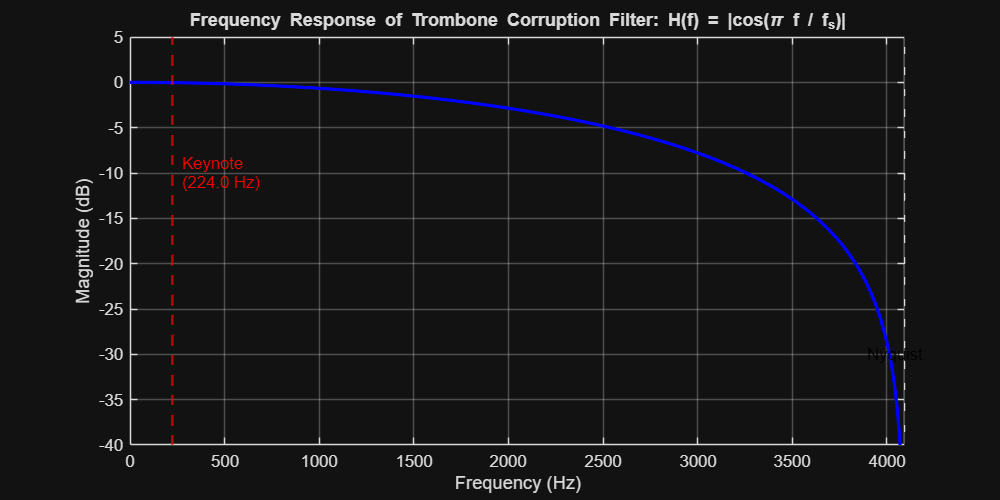


% Figure 6: Frequency response of the trombone corruption filter
figure('Position', [100, 100, 800, 400]);
f_filter = linspace(0, trombone_fs/2, 1000);
H = abs(0.5 * (1 + exp(-1j*2*pi*f_filter/trombone_fs)));
plot(f_filter, 20*log10(H + eps), 'b-', 'LineWidth', 2);
xlabel('Frequency (Hz)'); 
ylabel('Magnitude (dB)');
title('Frequency Response of Trombone Corruption Filter: H(f) = |cos(\pi f / f_s)|');
grid on;
xlim([0, trombone_fs/2]);
ylim([-40, 5]);

% Adding annotations
hold on;
xline(trombone_keynote, 'r--', 'LineWidth', 1.5);
text(trombone_keynote+50, -10, sprintf('Keynote\n(%.1f Hz)', trombone_keynote), 'Color', 'r');
xline(trombone_fs/2, 'k--', 'LineWidth', 1);
text(trombone_fs/2-200, -30, 'Nyquist', 'Color', 'k');
hold off;


%% SUMMARY REPORT
fprintf('\n');
fprintf('%s\n', repmat('=', 1, 70));

fprintf('SUMMARY REPORT\n');

SUMMARY REPORT


fprintf('%s\n', repmat('=', 1, 70));


fprintf('\n1. SIGNAL DURATION:\n');


1. SIGNAL DURATION:


fprintf('   Cello: %.3f seconds\n', cello_time);

   Cello: 1.134 seconds


fprintf('   Trombone: %.3f seconds\n', trombone_time);

   Trombone: 1.134 seconds



fprintf('\n2. KEYNOTE FREQUENCIES:\n');


2. KEYNOTE FREQUENCIES:


fprintf('   Cello: %.2f Hz\n', cello_keynote);

   Cello: 224.00 Hz


fprintf('   Trombone: %.2f Hz\n', trombone_keynote);

   Trombone: 224.00 Hz



fprintf('\n3. OVERTONE RELATIONSHIP:\n');


3. OVERTONE RELATIONSHIP:


fprintf('   Both instruments show overtones at integer multiples of the keynote.\n');

   Both instruments show overtones at integer multiples of the keynote.


fprintf('   This confirms the harmonic series: f_k = k * f_0 for k = 1, 2, 3, ...\n');

   This confirms the harmonic series: f_k = k * f_0 for k = 1, 2, 3, ...



fprintf('\n4. NUMBER OF OVERTONES DETECTED:\n');


4. NUMBER OF OVERTONES DETECTED:


fprintf('   Cello: %d overtones (up to 5 kHz)\n', overtone_count_cello);

   Cello: 10 overtones (up to 5 kHz)


fprintf('   Trombone: %d overtones\n', overtone_count_trombone);

   Trombone: 4 overtones


fprintf(' The cello has more detectable overtones than the trombone in this recording.\n');

 The cello has more detectable overtones than the trombone in this recording.



fprintf('\n5. NOISE ANALYSIS:\n');


5. NOISE ANALYSIS:


fprintf('    Strong 50 Hz noise detected in both recordings.\n');

    Strong 50 Hz noise detected in both recordings.


fprintf('   This is mains hum from the tape recorder''s power supply.\n');

   This is mains hum from the tape recorder's power supply.


fprintf('   The recorder was likely not properly grounded or had a faulty capacitor.\n');

   The recorder was likely not properly grounded or had a faulty capacitor.


fprintf('   (As hinted: "the tape recorder was not battery charged")\n');

   (As hinted: "the tape recorder was not battery charged")



fprintf('\n6. CELLO CORRUPTION:\n');


6. CELLO CORRUPTION:


fprintf('   Formula: y[n] = n * x[2n+1] + 5\n');

   Formula: y[n] = n * x[2n+1] + 5


fprintf('   Effect: Downsampling + non-uniform amplitude scaling + DC offset\n');

   Effect: Downsampling + non-uniform amplitude scaling + DC offset


fprintf('   Recoverable: Yes (but only odd-indexed samples, n>0)\n');

   Recoverable: Yes (but only odd-indexed samples, n>0)



fprintf('\n7. TROMBONE CORRUPTION:\n');


7. TROMBONE CORRUPTION:


fprintf('   Formula: y[n] = (x[n] + x[n-1])/2\n');

   Formula: y[n] = (x[n] + x[n-1])/2


fprintf('   Effect: Low-pass filtering (2-point moving average)\n');

   Effect: Low-pass filtering (2-point moving average)


fprintf('   Frequency response: |H(f)| = |cos(pi*f/fs)|\n');

   Frequency response: |H(f)| = |cos(pi*f/fs)|


fprintf('   Recoverable: Yes (using inverse filtering or sequential recovery)\n');

   Recoverable: Yes (using inverse filtering or sequential recovery)



fprintf('\n%s\n', repmat('=', 1, 70));

fprintf('END OF MILESTONE 1 ANALYSIS\n');

END OF MILESTONE 1 ANALYSIS


fprintf('%s\n', repmat('=', 1, 70));